clc;
clear;
close all;

% material = ["bottle", "cable", "capsule", "carpet", "grid", "hazelnut", "leather", "metal_nut", "pill", "screw", "tile", "toothbrush", "transistor", "wood", "zipper"];

material = ["hazelnut"];
extractor = cell(length(material));

% Create structs for each element with names and multiple imds
for counter = 1:length(material)
    element(counter).name = material(counter);
    element(counter).imds = [imageDatastore(["00_data/"+material(counter)+"/train/","00_data/"+material(counter)+"/test/"], "FileExtensions",".png", "IncludeSubfolders",true, "LabelSource","foldernames")];
    [element(counter).imds_train, element(counter).imds_test] = splitEachLabel(element(counter).imds, 0.7, "randomized");
end

% 1st bottle w/o histeq --> 0.6
% 2nd bottle w/ histeq --> 0.74

% Add own extractor for each set of pictures
for counter = 1:length(material)
    if material(counter) == "bottle"
        extractor{counter} = @bottleBagOfFeaturesExtractor;
    end
    if material(counter) == "cable"
        extractor{counter} = @cableBagOfFeaturesExtractor;
    end
    if material(counter) == "capsule"
        extractor{counter} = @capsuleBagOfFeaturesExtractor;
    end
    if material(counter) == "carpet"
        extractor{counter} = @carpetBagOfFeaturesExtractor;
    end
    if material(counter) == "grid"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "hazelnut"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "leather"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "metal_nut"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "pill"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "screw"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "tile"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "toothbrush"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "transistor"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "wood"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "zipper"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
end


% Create classifier with bovw
for counter = 1:length(element)
    % only debugging
    extractor{counter}
    % end debugging
    element(counter).bag = bagOfFeatures(element(counter).imds_train, 'CustomExtractor', extractor{counter});
    element(counter).classifier = trainImageCategoryClassifier(element(counter).imds_train, element(counter).bag);
    element(counter).conf_matrix = evaluate(element(counter).classifier, element(counter).imds_test)
end

ans = function_handle with value:
    @ownBagOfFeaturesExtractor


Creating Bag-Of-Features.
-------------------------
* Image category 1: crack
* Image category 2: cut
* Image category 3: good
* Image category 4: hole
* Image category 5: print
* Extracting features using a custom feature extraction function: ownBagOfFeaturesExtractor.

* Extracting features from 352 images...done. Extracted 23068672 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 2 has the least number of strongest features: 629146.
** Using the strongest 629146 features from each of the other image categories.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 3145730
* Number of clusters          : 500
* Initializing cluster centers...100.00%.
* Clusterin

Training an image category classifier for 5 categories.
--------------------------------------------------------
* Category 1: crack
* Category 2: cut
* Category 3: good
* Category 4: hole
* Category 5: print

* Encoding features for 352 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.



Evaluating image category classifier for 5 categories.
-------------------------------------------------------

* Category 1: crack
* Category 2: cut
* Category 3: good
* Category 4: hole
* Category 5: print

* Evaluating 149 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                        PREDICTED
KNOWN    | crack   cut    good   hole   print   
------------------------------------------------
crack    | 0.00    0.80   0.00   0.00   0.20    
cut      | 0.00    1.00   0.00   0.00   0.00    
good     | 0.02    0.69   0.00   0.17   0.12    
hole     | 0.00    1.00   0.00   0.00   0.00    
print    | 0.00    0.80   0.00   0.20   0.00    

* Average Accuracy is 0.20.



element = struct with fields:
           name: "hazelnut"
           imds: [1×1 matlab.io.datastore.ImageDatastore]
     imds_train: [1×1 matlab.io.datastore.ImageDatastore]
      imds_test: [1×1 matlab.io.datastore.ImageDatastore]
            bag: [1×1 bagOfFeatures]
     classifier: [1×1 imageCategoryClassifier]
    conf_matrix: [5×5 double]


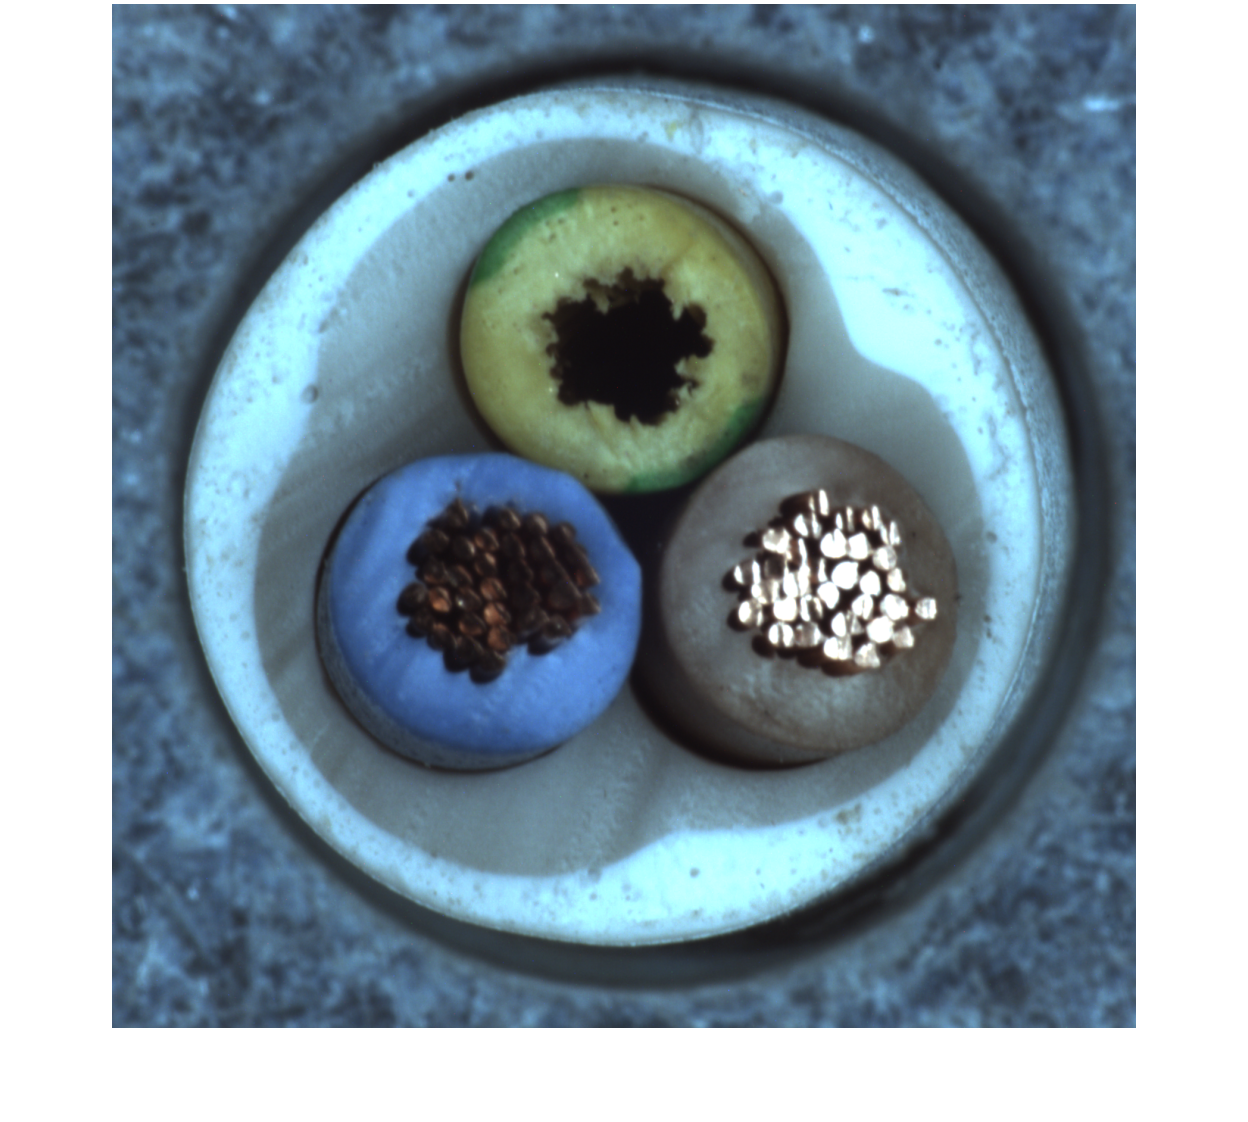

original = imread("00_data/cable/test/missing_wire/001.png");

I = imcrop(original,[110 110 800 800]);

grayImage = rgb2gray(I);

contrastImage = histeq(grayImage);

gausImage = imgaussfilt(grayImage, 5);

binImage = imbinarize(contrastImage, "adaptive");

se = eye(5);

dilImage = imdilate(binImage, se);
eroImage = imerode(dilImage, se);

closedImage = imopen(binImage,se);

img = closedImage;

imshow(original)

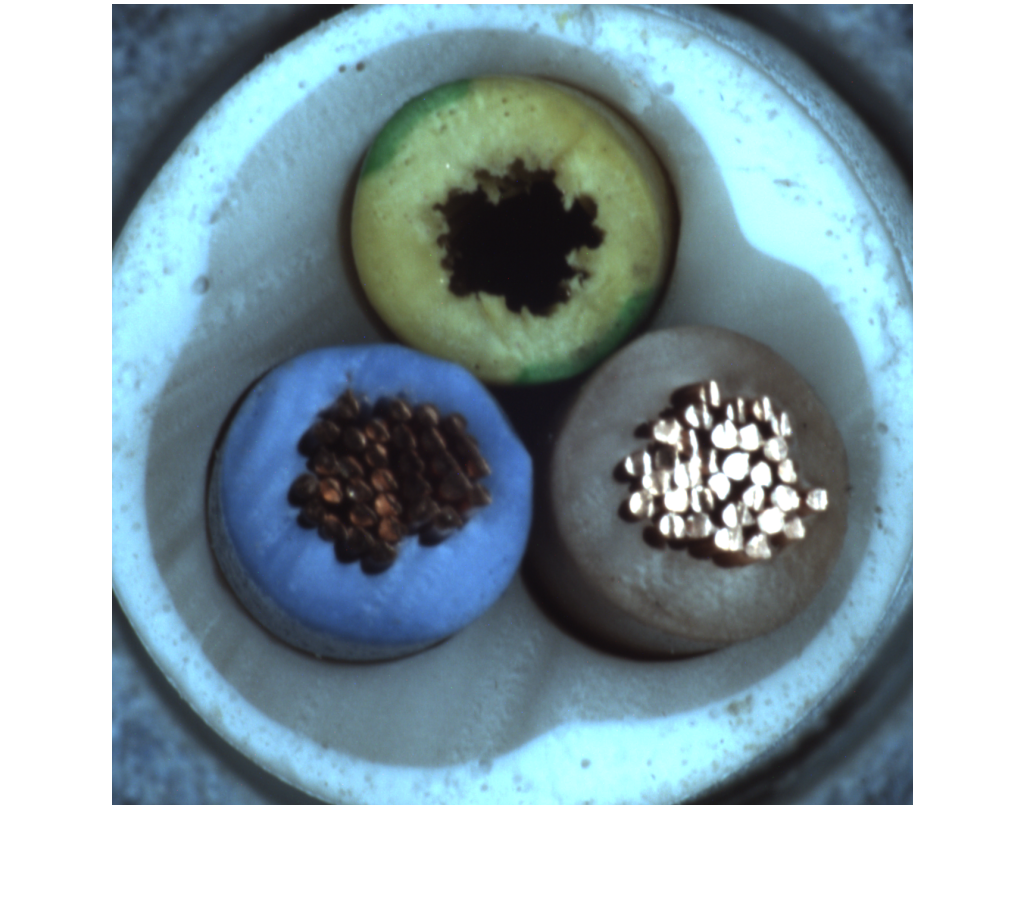

imshow(I)

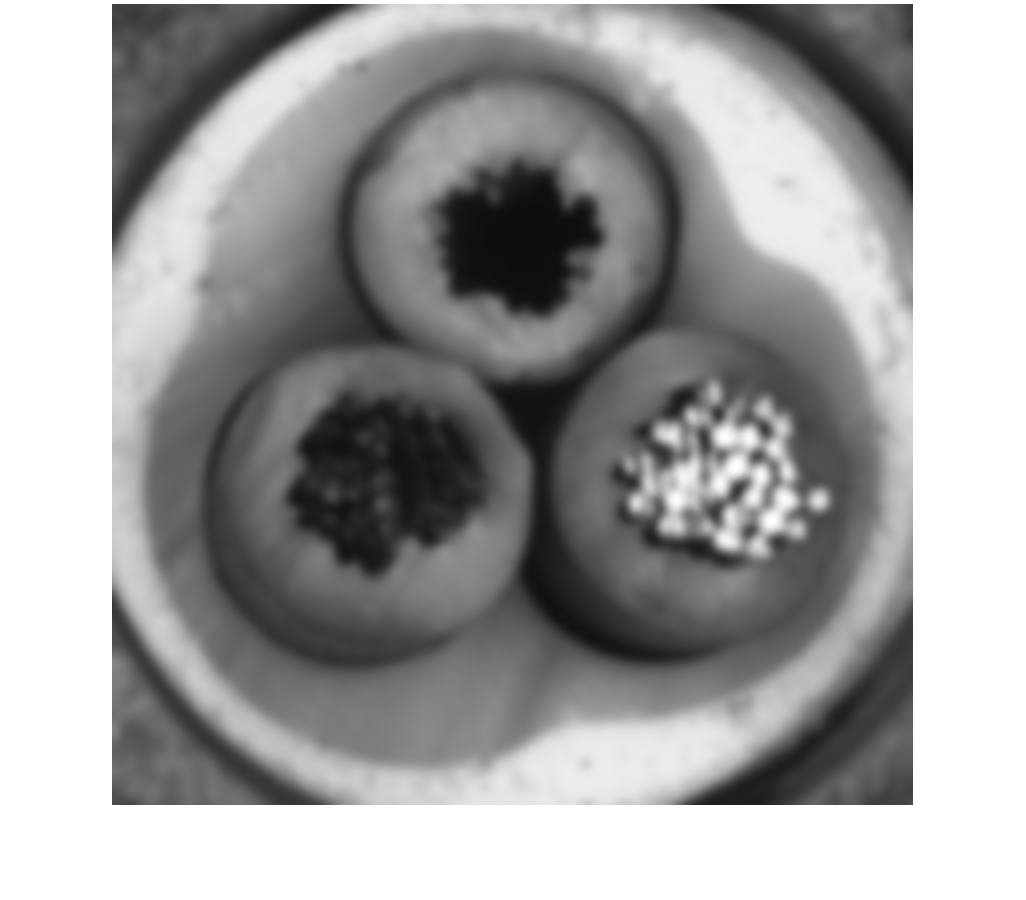

imshow(gausImage)

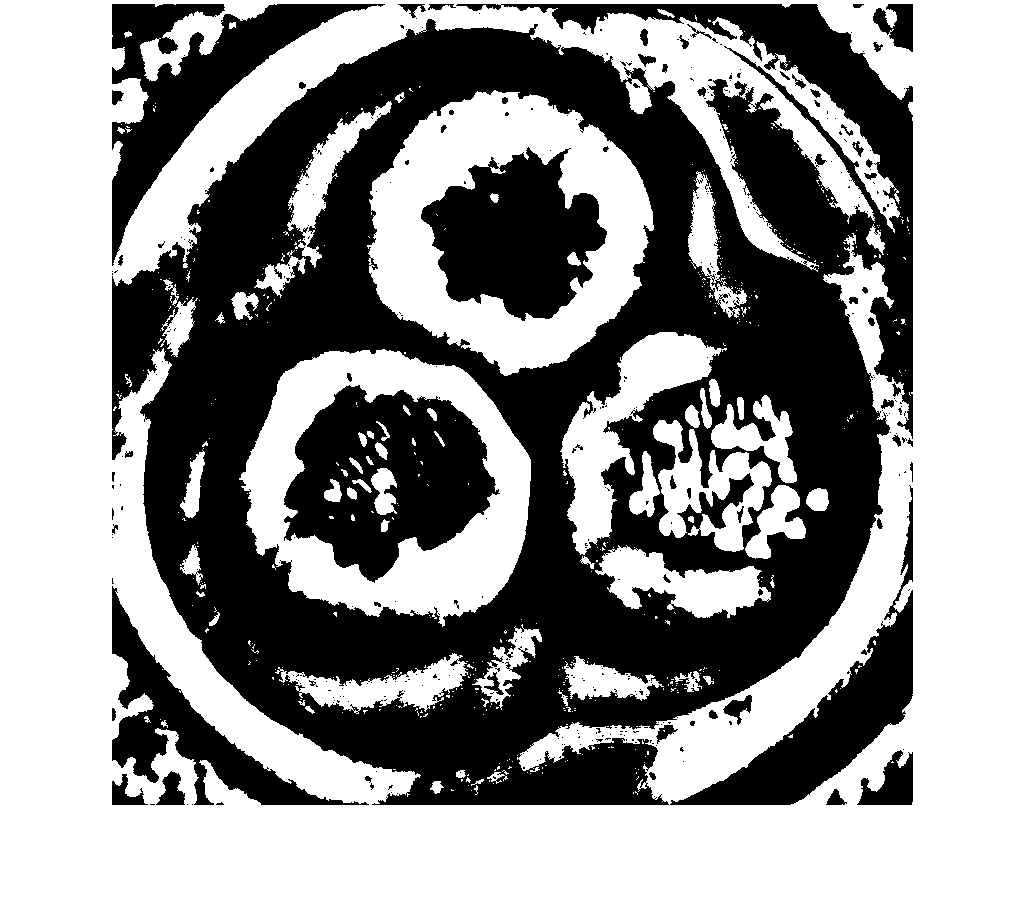

imshow(binImage)

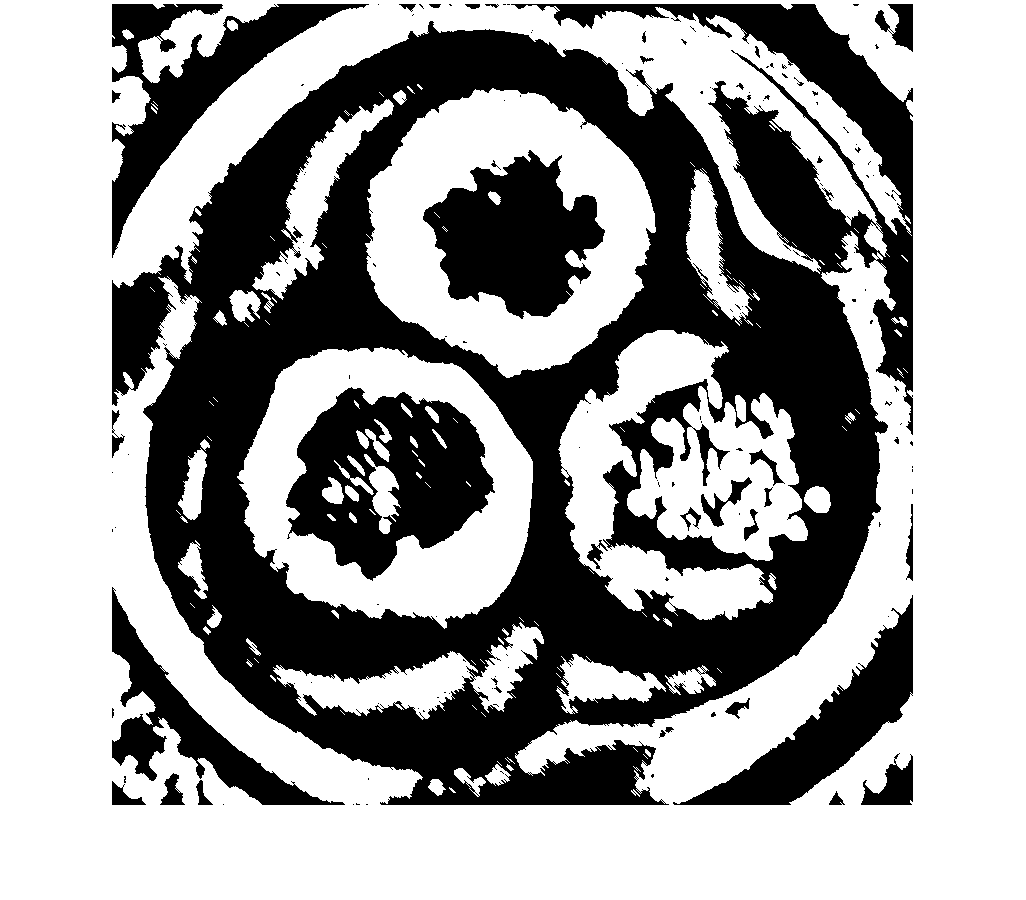

imshow(dilImage)

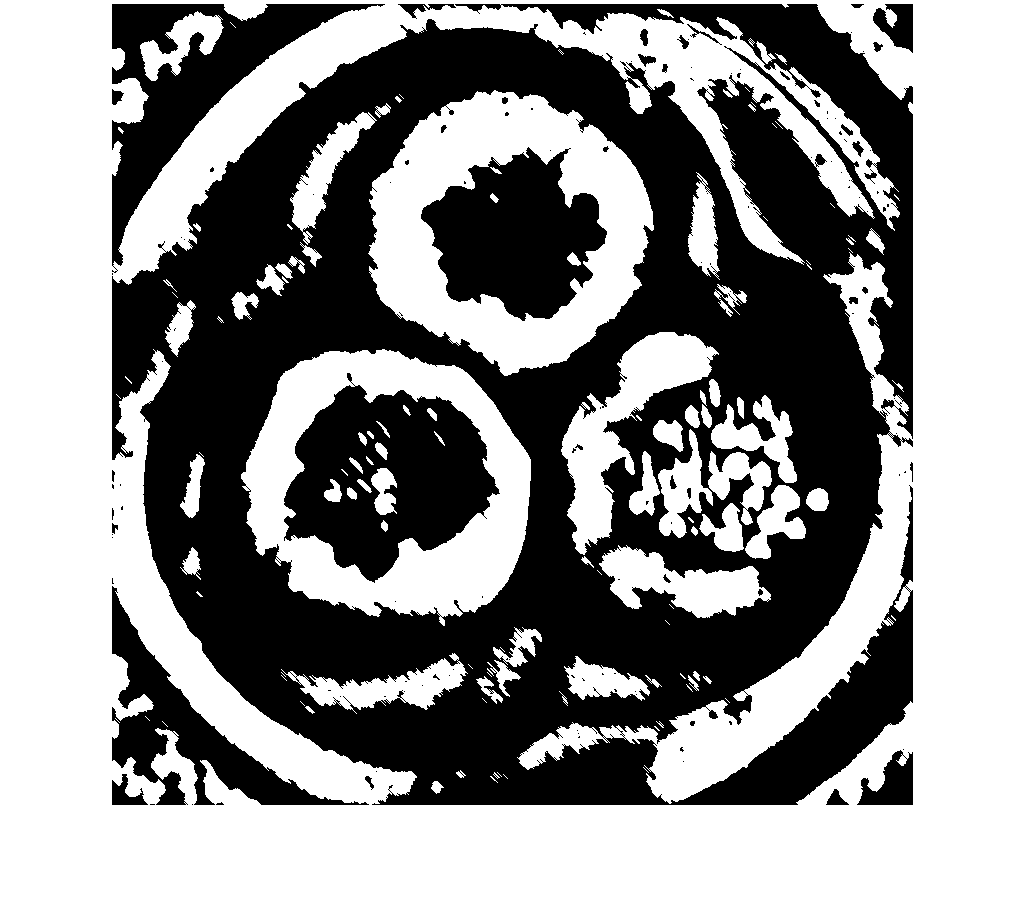

imshow(img)